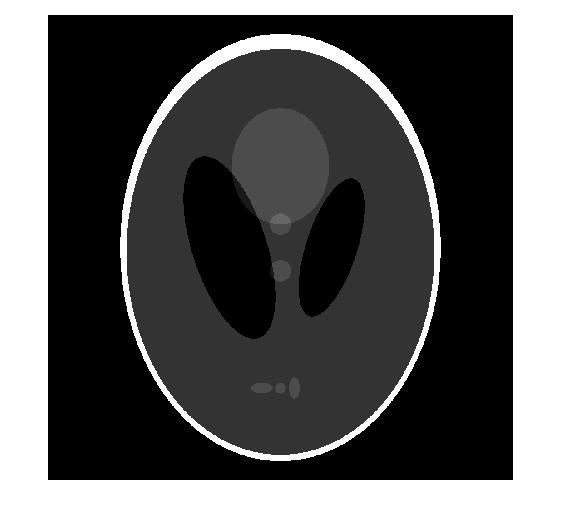

GT=phantom("Modified Shepp-Logan",1024);
imshow(GT);

compressing_factor=2;

shifted_GT=zeros(size(GT));
shifted_GT(:,1:end-1)=GT(:,2:end);
compressed=compress(GT,compressing_factor);
imshow(compressed);
compressed_shifted=compress(shifted_GT,compressing_factor);
imshow(compressed_shifted);

[row,col]=find(compressed_shifted==0);
super_reso=zeros(512,1024);

